clear all

fn = "2025-01-26-21-51-42.bag";

bag = rosbag(fn);

t_start = 1 * 1000 ; % in ms
t_end = 8*1000 + t_start;  % in ms

% bag = rosbag("bags/2025-01-16-16-08-08.bag");


setPointTopic = select(bag,'Topic','/setpoint');
botstatetopic = select(bag,'Topic','/state');

botstatePtopic = select(bag,'Topic','/state_p');
errorTopic = select(bag,'Topic','/error');
cmdTopic = select(bag,'Topic','/cmd');



setPointmsgs = readMessages(setPointTopic,'DataFormat','struct');
[sp, t_sp] = pose2mat(setPointmsgs);

msgPose = readMessages(botstatetopic,'DataFormat','struct');
[pose, t_pose]=pose2mat(msgPose);


P_Position_msgs = readMessages(botstatePtopic,'DataFormat','struct');
[p, t_p]=pose2mat(P_Position_msgs);


errors_msgs = readMessages(errorTopic,'DataFormat','struct');
[ee, t_e]=vec3tomat(errors_msgs);

cmd_msgs = readMessages(cmdTopic,'DataFormat','struct');
[cmd, t_c]=twist2mat(cmd_msgs);


start_sp = find(t_sp>t_start,1); 
start_p = find(t_p>t_start,1);
start_e = find(t_e>t_start,1); 
start_c = find(t_c>t_start,1); 
cutoff_sp = find(t_sp>t_end,1); 
cutoff_p = find(t_p>t_end,1); 
cutoff_e = find(t_e>t_end,1); 
cutoff_c = find(t_c>t_end,1); 

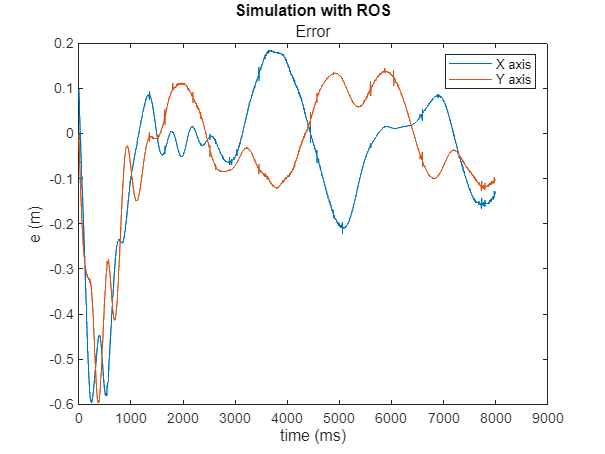


plot(t_e(start_e:cutoff_e)-t_start,ee(start_e:cutoff_e,:))
subtitle("Error")
title("Simulation with ROS")
legend('X axis','Y axis','Location','northeast')
ylabel("e (m)")
xlabel("time (ms)")

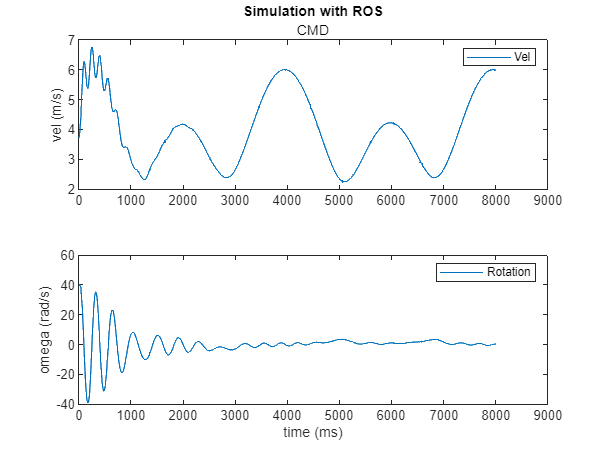

figure
subplot(2,1,1);
plot(t_c(start_c:cutoff_c)-t_start,cmd(start_c:cutoff_c,1))
title("Simulation with ROS")
legend('Vel','Location','northeast')
ylabel("vel (m/s)")
subtitle("CMD")
subplot(2,1,2); 
plot(t_c(start_c:cutoff_c)-t_start,cmd(start_c:cutoff_c,2))
legend("Rotation",'Location','northeast')
ylabel("omega (rad/s)")
xlabel("time (ms)")

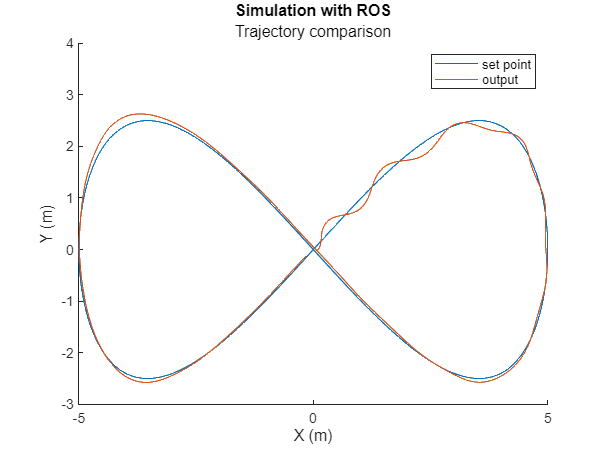


figure
hold on
    plot(sp(start_sp:cutoff_sp,1),sp(start_sp:cutoff_sp,2))
    plot(p(start_p:cutoff_p,1),p(start_p:cutoff_p,2))
hold off
title("Simulation with ROS")
subtitle("Trajectory comparison")
legend("set point","output")
ylim([-3 4])
ylabel("Y (m)")
xlabel("X (m)")


function [matrix,t] = pose2mat(msgs)
    matrix = zeros(numel(msgs),2);
    t = zeros(numel(msgs),1);
    for i=1:numel(msgs)
        matrix(i,1) = msgs{i,1}.Pose.Position.X;
        matrix(i,2) = msgs{i,1}.Pose.Position.Y;
        t(i,1) = 10^3* msgs{i,1}.Header.Stamp.Sec + 10^-6 * msgs{i,1}.Header.Stamp.Nsec;
    end

end

function [matrix,t] = vec3tomat(msgs)
    matrix = zeros(numel(msgs),2); % x y magnitude in column
    t = zeros(numel(msgs),1); % time in milliseconds
    for i=1:numel(msgs)
        matrix(i,1) = msgs{i,1}.Vector.X;
        matrix(i,2) = msgs{i,1}.Vector.Y;
        % matrix(i,3) = sqrt(msgs{i,1}.Vector.X^2+msgs{i,1}.Vector.Y^2);
        t(i,1) = 10^3* msgs{i,1}.Header.Stamp.Sec + 10^-6 * msgs{i,1}.Header.Stamp.Nsec;
    end

end

function [matrix,t] = twist2mat(msgs)
    matrix = zeros(numel(msgs),2); % x y magnitude in column
    t = zeros(numel(msgs),1); % time in milliseconds
    for i=1:numel(msgs)
        matrix(i,1) = msgs{i,1}.Twist.Linear.X;
        matrix(i,2) = msgs{i,1}.Twist.Angular.Z;
        % matrix(i,3) = sqrt(msgs{i,1}.Vector.X^2+msgs{i,1}.Vector.Y^2);
        t(i,1) = 10^3* msgs{i,1}.Header.Stamp.Sec + 10^-6 * msgs{i,1}.Header.Stamp.Nsec;
    end

end